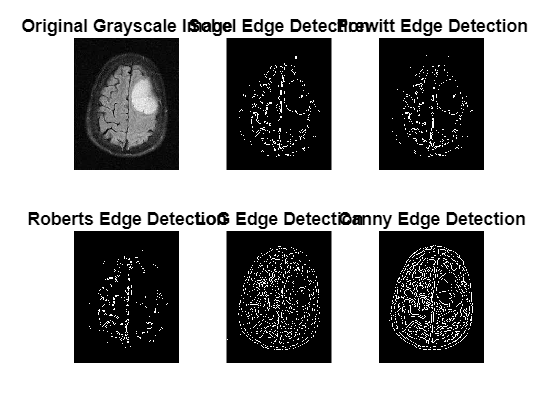

% Read image
img = imread("Te-me_0082.jpg");

% Convert to grayscale if image is RGB
if size(img,3) == 3
    gray = rgb2gray(img);
else
    gray = img;
end

figure;

% Original Image
subplot(2,3,1);
imshow(gray);
title('Original Grayscale Image');

% Sobel Edge Detection
sobelEdge = edge(gray, 'sobel');
subplot(2,3,2);
imshow(sobelEdge);
title('Sobel Edge Detection');

% Prewitt Edge Detection
prewittEdge = edge(gray, 'prewitt');
subplot(2,3,3);
imshow(prewittEdge);
title('Prewitt Edge Detection');

% Roberts Edge Detection
robertsEdge = edge(gray, 'roberts');
subplot(2,3,4);
imshow(robertsEdge);
title('Roberts Edge Detection');

% LoG (Laplacian of Gaussian)
logEdge = edge(gray, 'log');
subplot(2,3,5);
imshow(logEdge);
title('LoG Edge Detection');

% Canny Edge Detection
cannyEdge = edge(gray, 'canny');
subplot(2,3,6);
imshow(cannyEdge);
title('Canny Edge Detection');

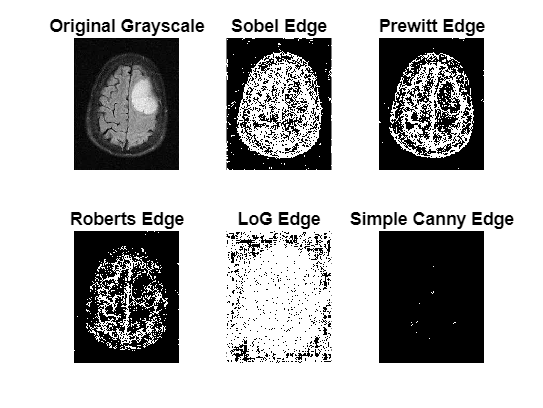




% Read image
img = imread("Te-me_0082.jpg");

% Convert to grayscale if needed
if size(img,3) == 3
    gray = double(rgb2gray(img));
else
    gray = double(img);
end

% Normalize
gray = gray / 255;

% --- Define Kernels ---
% Sobel
sobel_x = [-1 0 1; -2 0 2; -1 0 1];
sobel_y = sobel_x';

% Prewitt
prewitt_x = [-1 0 1; -1 0 1; -1 0 1];
prewitt_y = prewitt_x';

% Roberts
roberts_x = [1 0; 0 -1];
roberts_y = [0 1; -1 0];

% LoG Kernel (5x5, approximate)
LoG = [0 0 -1 0 0;
       0 -1 -2 -1 0;
      -1 -2 16 -2 -1;
       0 -1 -2 -1 0;
       0 0 -1 0 0];

% --- Convolution Function ---
conv2D = @(img,kernel) conv2(img, kernel, 'same');

% --- Compute Edges ---
% Sobel
sobel_edge = sqrt(conv2D(gray, sobel_x).^2 + conv2D(gray, sobel_y).^2);
sobel_edge = sobel_edge > 0.2; % Threshold

% Prewitt
prewitt_edge = sqrt(conv2D(gray, prewitt_x).^2 + conv2D(gray, prewitt_y).^2);
prewitt_edge = prewitt_edge > 0.2;

% Roberts
roberts_edge = sqrt(conv2D(gray, roberts_x).^2 + conv2D(gray, roberts_y).^2);
roberts_edge = roberts_edge > 0.1;

% LoG
log_edge = abs(conv2D(gray, LoG));
log_edge = log_edge > 0.03;

% Simple Canny-like (Gaussian blur + gradient magnitude + threshold)
G = fspecial('gaussian',[5 5],1); % Gaussian kernel
smoothed = conv2D(gray, G);
[grad_x, grad_y] = gradient(smoothed);
grad_mag = sqrt(grad_x.^2 + grad_y.^2);
canny_edge = grad_mag > 0.15;

% --- Plot All ---
figure;

subplot(2,3,1); imshow(gray); title('Original Grayscale');
subplot(2,3,2); imshow(sobel_edge); title('Sobel Edge');
subplot(2,3,3); imshow(prewitt_edge); title('Prewitt Edge');
subplot(2,3,4); imshow(roberts_edge); title('Roberts Edge');
subplot(2,3,5); imshow(log_edge); title('LoG Edge');
subplot(2,3,6); imshow(canny_edge); title('Simple Canny Edge');